# Vehicle Platooning with Lateral Control

This example demonstrates how to incorporate lateral control for vehicle platooning applications. 

A platoon consists of multiple vehicles traveling in-line maintaining close, uniform, and constant spacing. Vehicle Platooning  presents numerous benefits including improved traffic flow, safety, and fuel economy. 

Platooning has the following control objectives [1].

- Individual vehicle stability — Spacing error for each following vehicle converges to zero if the preceding vehicle is traveling at constant speed.

- String stability — Spacing errors do not amplify as they propagate towards the tail of the vehicle string.

In this example, we define an additional control objective.

- Lateral Control — Each platoon vehicle's lateral deviation from the reference path converges to zero even on roads with varying curvature.

## Platooning Model

Open the Simulink® model.

clear;clc;
mdl = 'PlatoonWithLateralControlExample';
open_system(mdl);

Specify Simulation run time and sample time.

T = 180;  % Simulation time
Ts = 0.1; % Sample time

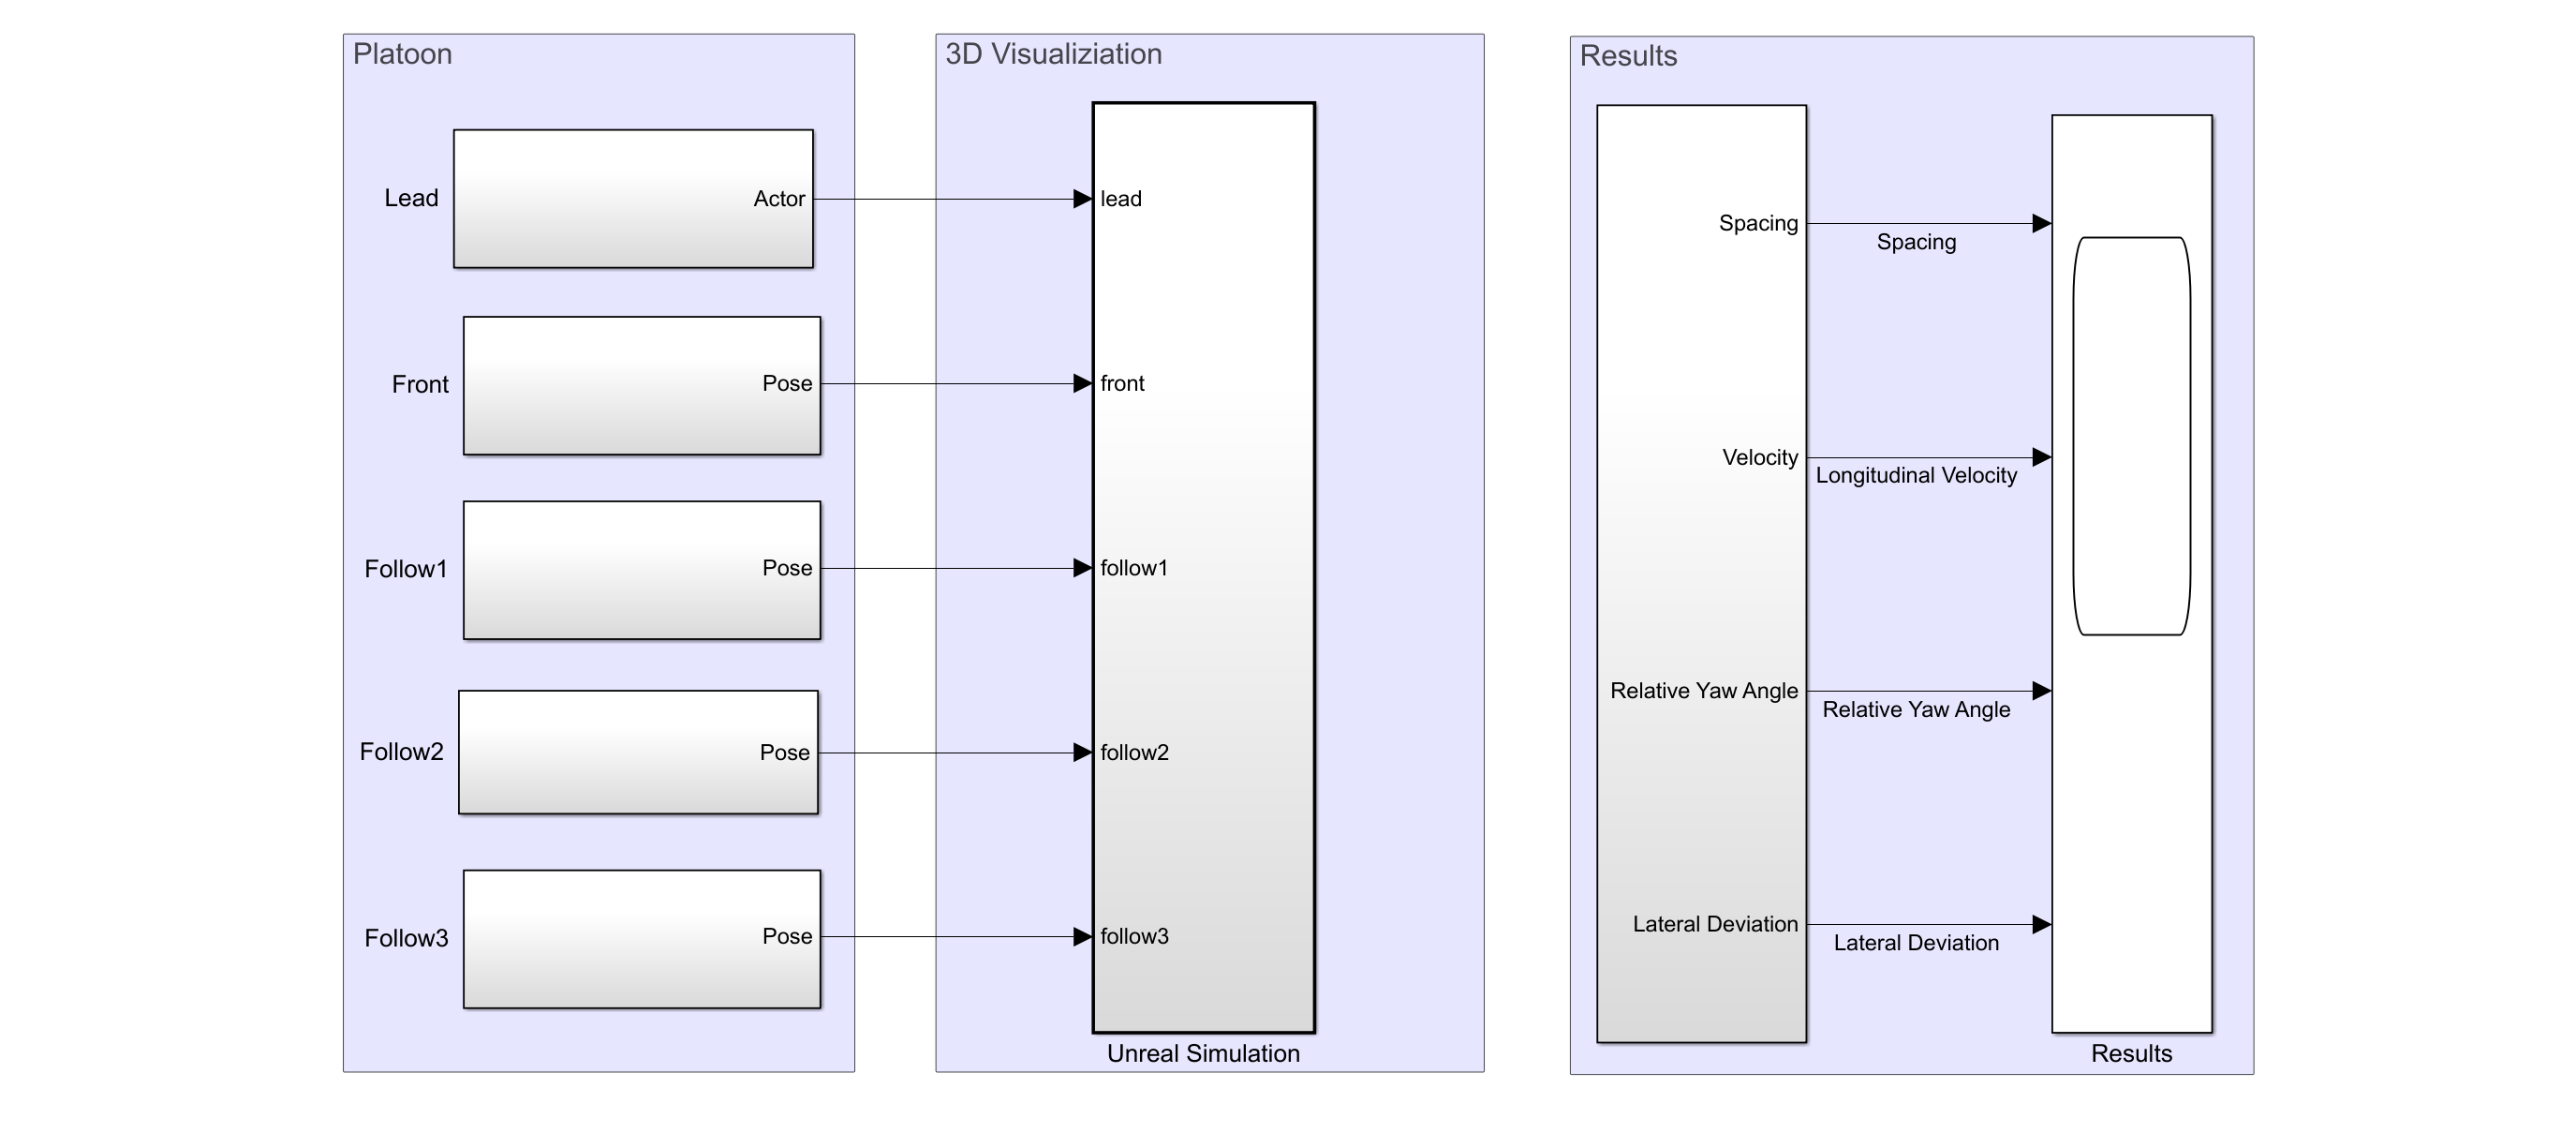

Each vehicle in the platoon is equiped with a two primary controllers 

- Spacing Controller — to control the longitudinal velocity of each vehicle and ensure a constant and uniformly spaced platoon

- Lateral Position Controller — to react to changes in the path's curvature and control the lateral deviation of the vehicle from the desired path

The lead vehicle does not have a spacing controller, instead it follows a given acceleration profile.  

#### Vehicle Dynamics

In this example, there are five vehicles in the platoon. Each vehicle is modeled as a truck-trailer system defined in 'truck_trailer_model'.

Here, we assume each vehicle has the same initial velocity of 15 m/s.

Vx0 = 15;                           % Initial Longitudinal Velocity [m/s]
[A,B,C] = truck_trailer_model(Vx0); % State Space Representaion of truck-trailer dynamics

#### Setting Longitudinal Acceleration Profile for Lead Vehicle

The lead vehicle is given a acceleration profile to follow. Below, you can choose between Constant Aceleration/Constant Velocity (ax = 0) and a Sinusoidal acceleration profile. If selecting the Sinusoidal Acceleration Profile, ensure to specify the amplitude of the Sinusoid below.

set_param('PlatoonWithLateralControlExample/Lead/Manual Switch','sw','1'); % profile -- Sinusoidal or Constant Acceleration Profile
amp = 1;             % Amplitude of Acceleration Profile if Sinusoidal Profile chosen above

#### Path Selection

This example has two reference paths to choose from.

- Straight Road — A straight 4-lane road. 

- Highway — A road imitating a real-world 4-lane highway scenario with a mix of straights and curves turning left and right. 

For the paths above, the vehicle will follow the right-most lane of the road.

addpath('Scenarios')
path = 'highway';               % Select Path for Platoon to Follow
[XRef,YRef,YawRef,VX,VY, time] = getPath(path,Ts,Vx0); % Reference Path -- [XRef, YRef, YawRef] [m, m, deg]

#### Setting Initial Vehicle Poses 

Here we specify the desired initial distance between vehicles and set the initial pose of each vehicle such that they are evenly spaced on the path.

L0 = 30;                                  % Initial Spacing of Vehicles
pose0 = evenlySpaceVehicles(L0, Vx0, Ts); % Array of indicies of initial vehicle pose 

lead_pose0    = [XRef(pose0(1)), YRef(pose0(1)), YawRef(pose0(1))];  % Lead Initial Pose
front_pose0   = [XRef(pose0(2)), YRef(pose0(2)), YawRef(pose0(2))];  % Front Initial Pose
follow1_pose0 = [XRef(pose0(3)), YRef(pose0(3)), YawRef(pose0(3))];  % Follow1 Initial Pose
follow2_pose0 = [XRef(pose0(4)), YRef(pose0(4)), YawRef(pose0(4))];  % Follow2 Initial Pose
follow3_pose0 = [XRef(pose0(5)), YRef(pose0(5)), YawRef(pose0(5))];  % Follow3 Initial Pose

## Controller Design

#### Spacing Control

In this example, the following vehicles all use the same sliding mode controller design with the following structure:


$$a_{\textrm{ego}} =\left(1-C_1 \right)a_{\textrm{front}} +C_1 a_{\textrm{lead}} -\left(2\zeta -C_1 \left(\zeta +\sqrt{\zeta^2 -1}\right)\right)\omega_n \left(v_{\textrm{ego}} -v_{\textrm{front}} \right)-\left(\zeta +\sqrt{\zeta^2 -1}\right)\omega_n C_{1\;} \left(v_{\textrm{ego}} -v_{\textrm{lead}} \right)-\omega_n^2 e_{\textrm{spacing}}$$
 

Here:

- $a_{\textrm{ego}}$, $v_{\textrm{ego}}$, $x_{\textrm{ego}}$, and $y_{\textrm{ego}}$ are the respective longitudinal acceleration, longitudinal velocity, and position coordinates of the ego vehicle —the trailing vehicle under control.

- $a_{\textrm{front}}$, $v_{\textrm{front}}$, $x_{\textrm{front}}$, and $y_{\textrm{front}}$ are the longitudinal acceleration,  longitduinal velocity, and position coordinates of the vehicle directly in front of the ego vehicle.

- $a_{\textrm{lead}}$ and $v_{\textrm{lead}}$  are the longitudinal acceleration and longitudinal velocity of the lead vehicle in the platoon.

- $e_{\textrm{spacing}}$ is the spacing error between vehicles. In this example, this error is specified using the Euclidean distance between the vehicles. 


$$e_{\textrm{spacing}} =L_{\textrm{des}} -\sqrt{{\left(x_{\textrm{ego}} -x_{\textrm{front}} \right)}^2 +{\left(y_{\textrm{ego}} -y_{\textrm{front}} \right)}^2 }$$


Each vehicle obtains this information from onboard sensors and wireless communication with the other vehicles in the platoon.

The parameters for the controller are as follows.

- $L_{\textrm{des}}$ — the desired following distance.

- $C_1$ — a constant that takes  on values between 0 and 1. This parameter is the weighting of the lead vehicle's speed and acceleration.

- $\zeta$—  the damping ratio.

- $\omega$ — the controller bandwidth.

The controller minimizes the velocity error $v_{\textrm{lead}} -v_{\textrm{ego}}$ , and minimizes the spacing error $e_{\textrm{spacing}}$ .

Define the initial controller parameters.

L = 25;       % Desired Front-to-Front Vehicle Spacing
C1 = 0.9;     % Gain specifying weight attributed to a_lead and v_lead
zeta = 2;     % Damping ratio 
omega = 0.5 ; % Bandwidth

#### Lateral Control

All vehicles in the platoon use the same lateral control structure.

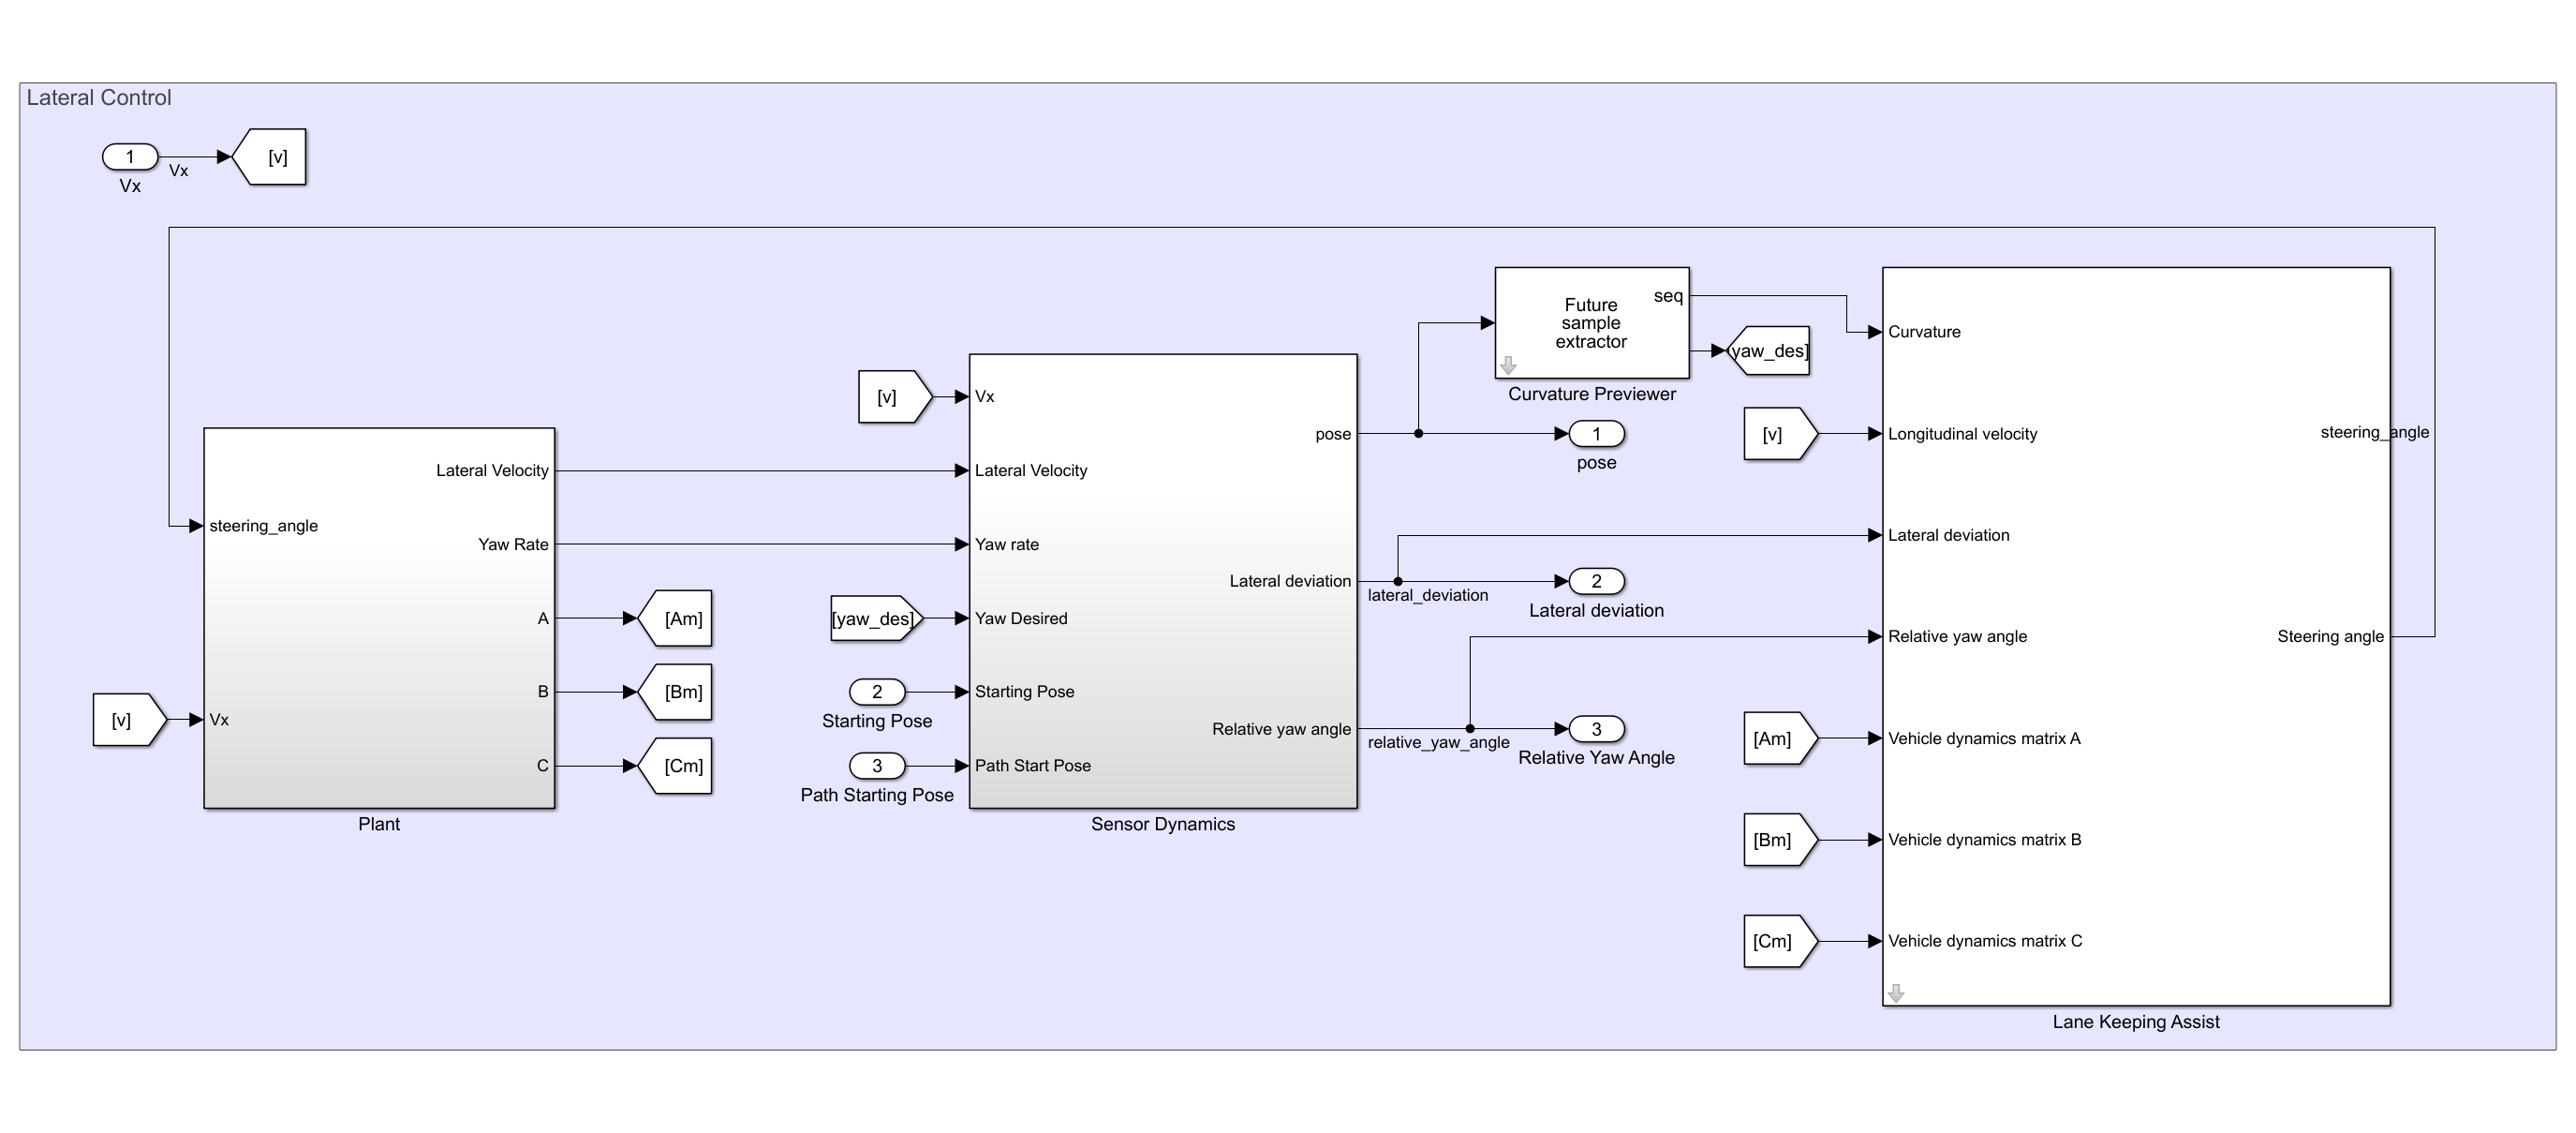

The Lateral Control subsystem accepts three inputs

- $v_x$ — the vehicle's longitudinal velocity

- Starting Pose — the vehicle's initial position (x and y coordinates) and heading (yaw angle)  

- Path Starting Pose — the initial position and heading from the reference path

Note: In this example it is assumed that the vehicle starts on that path, thus the Starting Pose and Path Starting Pose are the same.

**Plant**

The lateral vehicle dynamics are represented here using a Varying State Space model that updates at every time step to account for the non-constant velocity output by the Longitudinal Controller. 

**Sensor Dynamics and Curvature Previewer**

In this example, the Sensor Dynamics block outputs the lateral deviation and relative yaw angle. 

The dynamics for these outputs are as follows.

- Relative Yaw Angle — $e_2 =\int_0^t \overset{\ldotp }{\psi} \;\textrm{dt}-\psi_{\textrm{des}}$

- Lateral Deviation — $e_1 =\int_0^t \left({v_x e}_2 \;\;+v_{y\;} \right)\textrm{dt}$

Additionally, the Sensor Dynamics subsytem outputs the pose of the vehicle. This will be used to create and actor for visualization of the driving scenario.

The Curvature Previewer block outputs the previewed curvature with a look-ahead time of one second. Therefore, given a sample time 0.1, the prediction horizon `10` steps. 

The curvature used in this example is calculated based on the refererence path chosen above. The Curvature Previewer Block takes in the current vehicle pose in order to assess the vehicle's location along the path and return the desired vehicle heading (yaw angle) at that position.

Specify the prediction horizon and obtain the previewed curvature.

PredictionHorizon = 1/Ts;          % Number of time steps for Prediction Horizon
md = getCurvature(XRef,YRef,time); % Measured Disturbance -- curvature estimate along desired path

**Configuration of the Lane Keeping Assist System Block**

The LKA system is modeled in Simulink using the Lane Keeping Assist System block. The inputs to the LKA system block are:

- Previewed curvature 

- Ego longitudinal velocity

- Lateral deviation 

- Relative yaw angle

The output of the LKA system is the front steering angle of the ego car. Considering the physical limitations of the truck-trailer system, the steering angle is constrained to the range [-0.3,0.3] rad.

u_min = -.3;            % Minumim Steering Angle
u_max = .3;             % Maximum Steering Angle

## Results

Run the simulation.

% Model Setup
load PoseBus.mat;
mpcverbosity off;

sim(mdl);